# Devoir 2

## Initialisation

clc
clear all
close all

## 1 Limites de l'enveloppe de vol - Laboratoires #2 et #3

## Mise en mémoire des données

run('aircraft_data.m')

## 1.1

%
% Condition de vol
Ma_e = 0.2;
h_e  = 1500;

% Caractéristiques atmosphériques correspondant à la condition de vol. 
% Indication: Utilisez les formules exactes. Les valeurs numériques au
% niveau de la mer sont stockées dans "aircraft_data.m".

T_e    = T0 + (Th*h_e);
rho_e  = rho0 * (T_e/T0)^(-(1+g0/(R*Th)));
a_e    = sqrt(gamma*R*T_e);
VT_e   = Ma_e*a_e;
qbar_e = 0.5*rho_e*(VT_e^2);

% Résolution avec fsolve
% Indication: Complétez la fonction "trimmed_equations" qui contient les équations à résoudre.
% La fonction "fsolve" appelle cette fonction à chaque itération de l'optimisation jusqu'à 
% diminuer la norme de F sous un certain seul de tolérance 10^-9
% Faites un doc solve pour en savoir plus
[x F] = fsolve(@(x) trimmed_equations(x,qbar_e),[0 0 0]);


Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the value
of the function tolerance. However, the last step was ineffective.

<stopping criteria details>



% Vérifiez que la norme de F est proche de 0 (validité de la solution obtenue par fsolve) 
norm(F)

ans = 1.1917e-10


% Solution
alpha_e = x(1) % Angle d'attaque à l'équilibre

alpha_e = 0.3490

dths_e  = x(2) % Braque du plan horizontal réglable à l'équilibre

dths_e = 0.4052

Tm_e    = x(3) % Poussée totale à l'équilibre (Poussée des deux moteurs)

Tm_e = 4.3817e+04


% Indication: Utilisez la formule qui relie la poussée d'un SEUL moteur Tm_i à dth
dth_e   = (Tm_e/2)/(110000 - 75000*Ma_e - 7.5*(h_e) + 2*Ma_e*(h_e) + 62000*(Ma_e^2))  % Position de la manette des gaz à l'équilibre.

dth_e = 0.2523


% Les solutions trouvées respectent les contraintes spécifiées:
alpha_e_d = alpha_e*180/pi % on veut une réponse en degré et non en rad

alpha_e_d = 19.9976

dths_e_d = dths_e*180/pi

dths_e_d = 23.2168

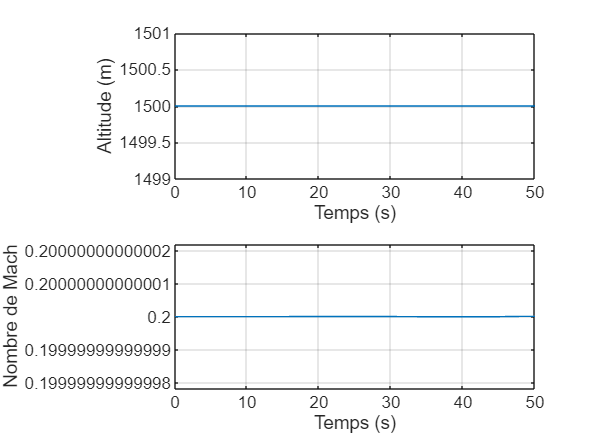


% *** Vérification de l'équilibrage ***

% Conditions initiales

% À l'équilibre en croisière, l'angle de tangage est égal à l'angle d'attaque.
theta_e   = alpha_e;

% Vecteurs des conditions initiales des intégrateurs pour partir de l'équilibre à t=0
Vb_e      = [VT_e*cos(theta_e) 0 VT_e*sin(theta_e)]';
Omegab_e  = [0 0 0 ]';
Po_e      = [0 0 -h_e]';
Euler_e   = [0 theta_e 0]';

% Valeurs d'équilibre des surfaces de contrôle
da_e      = 0;
de_e      = 0;
dr_e      = 0;

% Simulation
% Indication: Inspectez le schéma Simulink
sim('aircraft_BO_sim')

% Réponse en altitude
% Indication: Si tout va bien, l'altitude reste constante à h_e = 8000 m
subplot(211)
plot(Simulation_Data.time,Simulation_Data.signals(1).values)
xlabel('Temps (s)')
ylabel('Altitude (m)')
grid on

% Réponse en Mach
% Indication: Si tout va bien, le Mach reste constant à Ma_e = 0.75
subplot(212)
plot(Simulation_Data.time,Simulation_Data.signals(2).values)
xlabel('Temps (s)')
ylabel('Nombre de Mach')
grid on

## 1.2

%
%
% Condition de vol
Ma_e = 0.85;
h_e  = 7000;

% Caractéristiques atmosphériques correspondant à la condition de vol. 
% Indication: Utilisez les formules exactes. Les valeurs numériques au
% niveau de la mer sont stockées dans "aircraft_data.m".

T_e    = T0 + (Th*h_e);
rho_e  = rho0 * (T_e/T0)^(-(1+g0/(R*Th)));
a_e    = sqrt(gamma*R*T_e);
VT_e   = Ma_e*a_e;
qbar_e = 0.5*rho_e*(VT_e^2);

% Résolution avec fsolve
% Indication: Complétez la fonction "trimmed_equations" qui contient les équations à résoudre.
% La fonction "fsolve" appelle cette fonction à chaque itération de l'optimisation jusqu'à 
% diminuer la norme de F sous un certain seul de tolérance 10^-9
% Faites un doc solve pour en savoir plus
[x F] = fsolve(@(x) trimmed_equations(x,qbar_e),[0 0 0]);


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>



% Vérifiez que la norme de F est proche de 0 (validité de la solution obtenue par fsolve) 
norm(F)

ans = 5.8208e-11


% Solution
alpha_e = x(1) % Angle d'attaque à l'équilibre

alpha_e = 0.0208

dths_e  = x(2) % Braque du plan horizontal réglable à l'équilibre

dths_e = 0.0072

Tm_e    = x(3) % Poussée totale à l'équilibre (Poussée des deux moteurs)

Tm_e = 5.5161e+04


% Indication: Utilisez la formule qui relie la poussée d'un SEUL moteur Tm_i à dth
dth_e   = (Tm_e/2)/(110000 - 75000*Ma_e - 7.5*(h_e) + 2*Ma_e*(h_e) + 62000*(Ma_e^2))  % Position de la manette des gaz à l'équilibre.

dth_e = 0.5467


% Les solutions trouvées respectent les contraintes spécifiées:
alpha_e_d = alpha_e*180/pi % on veut une réponse en degré et non en rad

alpha_e_d = 1.1904

dths_e_d = dths_e*180/pi

dths_e_d = 0.4146

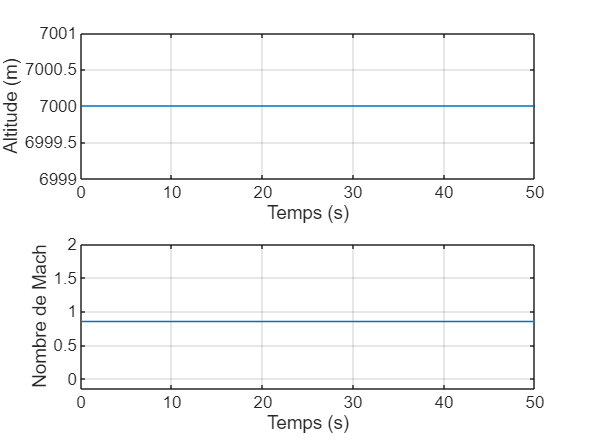


% *** Vérification de l'équilibrage ***

% Conditions initiales

% À l'équilibre en croisière, l'angle de tangage est égal à l'angle d'attaque.
theta_e   = alpha_e;

% Vecteurs des conditions initiales des intégrateurs pour partir de l'équilibre à t=0
Vb_e      = [VT_e*cos(theta_e) 0 VT_e*sin(theta_e)]';
Omegab_e  = [0 0 0 ]';
Po_e      = [0 0 -h_e]';
Euler_e   = [0 theta_e 0]';

% Valeurs d'équilibre des surfaces de contrôle
da_e      = 0;
de_e      = 0;
dr_e      = 0;

% Simulation
% Indication: Inspectez le schéma Simulink
sim('aircraft_BO_sim')

% Réponse en altitude
% Indication: Si tout va bien, l'altitude reste constante à h_e = 8000 m
subplot(211)
plot(Simulation_Data.time,Simulation_Data.signals(1).values)
xlabel('Temps (s)')
ylabel('Altitude (m)')
grid on

% Réponse en Mach
% Indication: Si tout va bien, le Mach reste constant à Ma_e = 0.75
subplot(212)
plot(Simulation_Data.time,Simulation_Data.signals(2).values)
xlabel('Temps (s)')
ylabel('Nombre de Mach')
grid on

## 1.3

%
%
% Condition de vol
Ma_e = 0.45;
h_e  = 11000;

% Caractéristiques atmosphériques correspondant à la condition de vol. 
% Indication: Utilisez les formules exactes. Les valeurs numériques au
% niveau de la mer sont stockées dans "aircraft_data.m".

T_e    = T0 + (Th*h_e);
rho_e  = rho0 * (T_e/T0)^(-(1+g0/(R*Th)));
a_e    = sqrt(gamma*R*T_e);
VT_e   = Ma_e*a_e;
qbar_e = 0.5*rho_e*(VT_e^2);

% Résolution avec fsolve
% Indication: Complétez la fonction "trimmed_equations" qui contient les équations à résoudre.
% La fonction "fsolve" appelle cette fonction à chaque itération de l'optimisation jusqu'à 
% diminuer la norme de F sous un certain seul de tolérance 10^-9
% Faites un doc solve pour en savoir plus
[x F] = fsolve(@(x) trimmed_equations(x,qbar_e),[0 0 0]);


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>



% Vérifiez que la norme de F est proche de 0 (validité de la solution obtenue par fsolve) 
norm(F)

ans = 2.1828e-11


% Solution
alpha_e = x(1) % Angle d'attaque à l'équilibre

alpha_e = 0.2548

dths_e  = x(2) % Braque du plan horizontal réglable à l'équilibre

dths_e = 0.2932

Tm_e    = x(3) % Poussée totale à l'équilibre (Poussée des deux moteurs)

Tm_e = 3.5662e+04


% Indication: Utilisez la formule qui relie la poussée d'un SEUL moteur Tm_i à dth
dth_e   = (Tm_e/2)/(110000 - 75000*Ma_e - 7.5*(h_e) + 2*Ma_e*(h_e) + 62000*(Ma_e^2))  % Position de la manette des gaz à l'équilibre.

dth_e = 1.1003


% Les solutions trouvées respectent les contraintes spécifiées:
alpha_e_d = alpha_e*180/pi % on veut une réponse en degré et non en rad

alpha_e_d = 14.6004

dths_e_d = dths_e*180/pi

dths_e_d = 16.7998

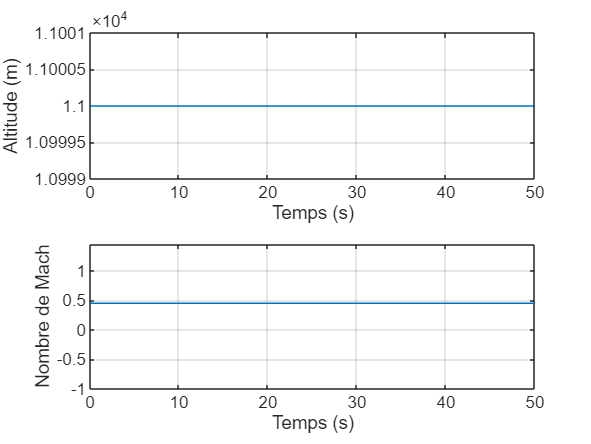


% *** Vérification de l'équilibrage ***

% Conditions initiales

% À l'équilibre en croisière, l'angle de tangage est égal à l'angle d'attaque.
theta_e   = alpha_e;

% Vecteurs des conditions initiales des intégrateurs pour partir de l'équilibre à t=0
Vb_e      = [VT_e*cos(theta_e) 0 VT_e*sin(theta_e)]';
Omegab_e  = [0 0 0 ]';
Po_e      = [0 0 -h_e]';
Euler_e   = [0 theta_e 0]';

% Valeurs d'équilibre des surfaces de contrôle
da_e      = 0;
de_e      = 0;
dr_e      = 0;

% Simulation
% Indication: Inspectez le schéma Simulink
sim('aircraft_BO_sim')

% Réponse en altitude
% Indication: Si tout va bien, l'altitude reste constante à h_e = 8000 m
subplot(211)
plot(Simulation_Data.time,Simulation_Data.signals(1).values)
xlabel('Temps (s)')
ylabel('Altitude (m)')
grid on

% Réponse en Mach
% Indication: Si tout va bien, le Mach reste constant à Ma_e = 0.75
subplot(212)
plot(Simulation_Data.time,Simulation_Data.signals(2).values)
xlabel('Temps (s)')
ylabel('Nombre de Mach')
grid on

## 1.4

%
h_e = [1000 1000 1000 5000 5000 5000 10000 10000 10000];
dths_e = [-3*pi/180 7*pi/180 17*pi/180 -3*pi/180 7*pi/180 17*pi/180 -3*pi/180 7*pi/180 17*pi/180];

for i=1:9
    T_e   = T0 + (Th*h_e(i));
    rho_e  = rho0 * (T_e/T0)^(-(1+g0/(R*Th)));
    a_e   = sqrt(gamma*R*T_e);
    vecteur = [dths_e(i), rho_e];

    [x F] = fsolve(@(x) trimmed_equations_delta_ths(x,vecteur),[0 0 0]);
    
    norme(i) =norm(F);
    alpha_e(i)  = x(1)*180/pi;
    Vt_e(i)   = x(2);
    Tm_e(i)    = x(3);
    Ma_e(i) = Vt_e(i)/a_e;
    dth_e(i) = (Tm_e(i)/2)/(110000 - 75000*Ma_e(i) - 7.5*(h_e(i)) + 2*Ma_e(i)*(h_e(i)) + 62000*(Ma_e(i)^2));
end 


Solver stopped prematurely.

fsolve stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+02.


Solver stopped prematurely.

fsolve stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+02.


Solver stopped prematurely.

fsolve stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+02.


Solver st

alpha_e
Vt_e
dth_e


## 1.5

%

## 2 Analyse d’un modèle d’état linéarisé - Laboratoire #4

## Mise en mémoire des données

load rapport_2_data.mat

## 2.1

% 
damp(rapport_2_data.A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
  0.00e+00                -1.00e+00       0.00e+00               Inf    
  0.00e+00                -1.00e+00       0.00e+00               Inf    
  0.00e+00                -1.00e+00       0.00e+00               Inf    
 -5.33e-01 + 1.64e+00i     3.09e-01       1.73e+00          1.87e+00    
 -5.33e-01 - 1.64e+00i     3.09e-01       1.73e+00          1.87e+00    
 -5.37e-04 + 7.46e-02i     7.20e-03       7.46e-02          1.86e+03    
 -5.37e-04 - 7.46e-02i     7.20e-03       7.46e-02          1.86e+03    
 -1.90e-04                 1.00e+00       1.90e-04          5.25e+03    
 -1.69e-01 + 1.55e+00i     1.08e-01       1.56e+00          5.92e+00    
 -1.69e-01 - 1.55e+00i     1.08e-01       1.56e+00 

[wn,zeta,p] = damp(rapport_2_data.A);

wn =          0
         0
         0
    1.7291
    1.7291
    0.0746
    0.0746
    0.0002
    1.5600
    1.5600


zeta =    -1.0000
   -1.0000
   -1.0000
    0.3085
    0.3085
    0.0072
    0.0072
    1.0000
    0.1082
    0.1082


p =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.5335 + 1.6448i
  -0.5335 - 1.6448i
  -0.0005 + 0.0746i
  -0.0005 - 0.0746i
  -0.0002 + 0.0000i
  -0.1689 + 1.5509i
  -0.1689 - 1.5509i


% Les poles doivent etre listés et identifié selon leur mode 

## 2.2

% 

## 2.3

Vecteur d'état:         ${\left\lbrack \Delta u\;\Delta w\;\Delta q\;\Delta \theta \right\rbrack }^{\top }$

Vecteur d'entrée:    ${\left\lbrack \Delta \delta_e \;\Delta \delta_{\textrm{th}} \right\rbrack }^{\top }$ 

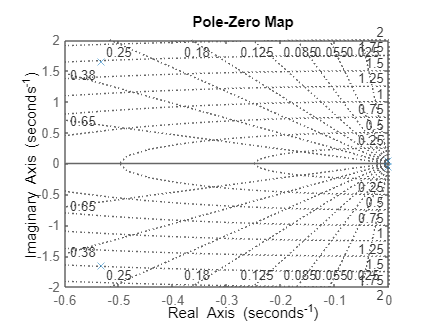

% *** MANQUE LA COMPARAISON ***
% Modèle longitudinal
theta_e = rapport_2_data.alpha_e;
VT_e    = rapport_2_data.VT_e;

% Constructions des matrices (Alon, Blon, Clon, Dlon)
Alon    = rapport_2_data.A([ 4 6 11 8 ],[ 4 6 11 8 ]);  
Blon    = rapport_2_data.B([ 4 6 11 8 ],[ 2 1 ]);      
Clon    = [cos(theta_e) sin(theta_e) 0 0;
           -sin(theta_e)/VT_e cos(theta_e)/VT_e 0 0; 
           0 0 1 0;
           0 0 0 1];
Dlon    = [0 0;
           0 0; 
           0 0; 
           0 0 ];

rapport_2_data.sys_lon = ss(Alon,Blon,Clon,Dlon);

% Mise en mémoire du modèle longitudinal de la condition
sys_lon = rapport_2_data.sys_lon;

% Carte des pôles
pzmap(sys_lon)
sgrid


% Pôles (amortissement et pulsation propre)
damp(sys_lon)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -9.00e-04 + 5.54e-02i     1.62e-02       5.54e-02         1.11e+03    
 -9.00e-04 - 5.54e-02i     1.62e-02       5.54e-02         1.11e+03    
 -5.33e-01 + 1.64e+00i     3.08e-01       1.73e+00         1.88e+00    
 -5.33e-01 - 1.64e+00i     3.08e-01       1.73e+00         1.88e+00    



% Comparaison


## 2.4

Vecteur d'état:         ${\left\lbrack \Delta v\;\Delta p\;\Delta r\;\Delta \phi \right\rbrack }^{\top }$

Vecteur d'entrée:    ${\left\lbrack \Delta \delta_a \;\Delta \delta_r \right\rbrack }^{\top }$ 

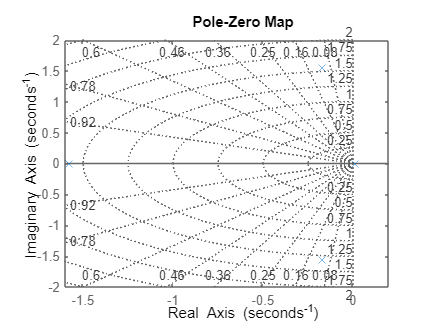

% *** MANQUE LA COMPARAISON ***
% Modèle latéral
Alat    = rapport_2_data.A([ 5 10 12 7 ],[ 5 10 12 7 ]);
Blat    = rapport_2_data.B([ 5 10 12 7 ],[ 4 3 ]);
Clat    = [   0 1 0 0;
              0 0 1 0; 
              0 0 0 1; 
              1/VT_e 0 0 0 ];
Dlat    = [   0 0 ;
              0 0;
              0 0;
              0 0 ];

rapport_2_data.sys_lat = ss(Alat,Blat,Clat,Dlat);

% Mise en mémoire du modèle longitudinal de la condition #i
sys_lat = rapport_2_data.sys_lat;

% Carte des pôles
pzmap(sys_lat)
sgrid


% Pôles (amortissement et pulsation propre)
damp(sys_lat)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.14e-02                -1.00e+00       1.14e-02        -8.75e+01    
 -1.69e-01 + 1.55e+00i     1.08e-01       1.56e+00         5.92e+00    
 -1.69e-01 - 1.55e+00i     1.08e-01       1.56e+00         5.92e+00    
 -1.57e+00                 1.00e+00       1.57e+00         6.36e-01    



% Comparaison


## 2.5

% 
%--------------------------------------------------------%
% Fonction de transfert Delta VT / Delta dth
%--------------------------------------------------------%
FT_VT_dth = tf(sys_lon(1,2))

FT_VT_dth =
 
      -0.2089 s^3 - 0.3803 s^2 + 7.724 s + 13.83
  ---------------------------------------------------
  s^4 + 1.068 s^3 + 2.994 s^2 + 0.008659 s + 0.009188
 
Continuous-time transfer function.
Model Properties



% Pôles/Zéros/Gain statique
zero5 = zero(FT_VT_dth)

zero1 =     6.0688
   -6.1025
   -1.7869


pole5 = damp(FT_VT_dth)

pole1 =     0.0554
    0.0554
    1.7289
    1.7289


gain5 = dcgain(FT_VT_dth)

gain1 = 1.5047e+03

## 2.6

% 
% Fonction de transfert Delta theta / Delta de
FT_dd_de = tf(sys_lon(4,1));
% Fonction de transfert Delta alpha / Delta de
FT_da_de = tf(sys_lon(2,1));

%--------------------------------------------------------%
% Fonction de transfert Delta Vz / Delta de
%--------------------------------------------------------%
FT_dVz_de = minreal(VT_e(FT_dd_de - FT_da_de));

FT_da_de =
 
   -0.03833 s^3 - 2.292 s^2 - 0.005854 s - 0.007443
  ---------------------------------------------------
  s^4 + 1.068 s^3 + 2.994 s^2 + 0.008659 s + 0.009188
 
Continuous-time transfer function.
Model Properties



% Pôles/Zéros/Gain statique
zero6 = zero(FT_dVz_de)

zero2 =  -59.7957 + 0.0000i
  -0.0012 + 0.0570i
  -0.0012 - 0.0570i


pole6 = damp(FT_dVz_de)

pole2 =     0.0554
    0.0554
    1.7289
    1.7289


gain6 = dcgain(FT_dVz_de)

gain2 = -0.8101

## 2.7

% 
%--------------------------------------------------------%
% Fonction de transfert Delta dphi / Delta dth
%--------------------------------------------------------%

% Fonction de transfert Delta dd / Delta dth
FT_dd_dth = tf(sys_lon(4,2))

% Fonction de transfert Delta da / Delta dth
FT_da_dth = tf(sys_lon(2,2))

% Fonction de transfert Delta dphi / Delta dth
FT_dphi_dth = minreal( FT_dd_dth - FT_da_dth )

% Pôles/Zéros/Gain statique
zero7 = zero(FT_dphi_dth)
pole7 = damp(FT_dphi_dth)
gain7 = dcgain(FT_dphi_dth)

## 2.8

% 
% Modèle longidudinal réduit au Short Period
Alon_red = sys_lon.A([ 6 11 ],[ 6 11 ]);
Blon_red = sys_lon.B([ 6 11 ],[ 2 ]);
Clon_red = sys_lon.C([ 6 11 ],[ 6 11 ]);
Dlon_red = sys_lon.D([ 6 11 ],[ 2 ]);
rapport_2_data.sys_lon_red = ss(Alon_red,Blon_red,Clon_red,Dlon_red);

% Mise en mémoire du modèle longitudinal de la condition #i    
sys_lon_red = rapport_2_data.sys_lon_red;

% Carte des pôles
pzmap(sys_lon_red);

% Pôles (amortissement et pulsation propre)
damp(sys_lon_red);

%--------------------------------------------------------%
% Fonction de transfert réduite Delta alpha / Delta de
%--------------------------------------------------------%
FT_alpha_de = tf(sys_lon_red(1,1));

% Pôles/Zéros/Gain statique
zero8 = zero(FT_alpha_de);
pole8 = damp(FT_alpha_de);
gain8 = dcgain(FT_alpha_de);



## 2.9

% 
%--------------------------------------------------------%
% Fonction de transfert Delta beta / Delta da
%--------------------------------------------------------%
FT_beta_da = tf(sys_lat(4,1));

% Pôles/Zéros/Gain statique
zero9 = zero(FT_beta_da);
pole9 = damp(FT_beta_da);
gain9 = dcgain(FT_beta_da);

## 2.10

% 
% Modèle latéral réduit au Roulis Pur
% Construction du modèle
Alon_red_r = sys_lat.A([ 2 ],[ 2 ]);
Blon_red_r = sys_lat.B([ 2 ],[ 1 ]);
Clon_red_r = sys_lat.C([ 1 ],[ 2 ]);
Dlon_red_r = [0];
rapport_2_data.sys_lat_red_r = ss(Alon_red_r,Blon_red_r,Clon_red_r,Dlon_red_r);


% Mise en mémoire du modèle longitudinal
sys_lat_red_r = rapport_2_data.sys_lat_red_r;
% Carte des pôles
pzmap(sys_lat_red_r);
% Pôles (amortissement et pulsation propre)
damp(sys_lat_red_r);

%--------------------------------------------------------%
% Fonction de transfert Delta p / Delta da
%--------------------------------------------------------%
FT_lan_red_r = tf(sys_lat_red_r_14( 1 , 1 ))

% Pôles/Zéros/Gain statique
zero10 = zero(FT_lan_red_r)
pole10 = damp(FT_lan_red_r)
gain10 = dcgain(FT_lan_red_r)

